## Equivalent Head Suplemental Figure

#### Load data

cd 'G:\My Drive\PhD_Research\BSF_Thesis\ModernAndSurfaceProcesses\Analyses\ModProcAnalyses\Groundwater'
cd EquivalentHeadSupPlot\data\input\

load('BrineDensity.mat')
load('BSFWellDatabase.mat')
load('Bflat30min.mat')

load('BLM93.mat')
load('BLM93C.mat')

# Calculate sample density at different temperatures

Using BLM-93C halite saturated equation (Bernau and Bowen, 2021 supplemental data). 

BflatHour = retime(Bflat30min, 'hourly', 'mean');

D0 = 1.215; 
A = -2.6072*10^-6;
B = -2.6370*10^-4;

BflatHour.HaliteSaturatedDensity =  A*(BflatHour.SoilTemp_C.^2) + B*(BflatHour.SoilTemp_C) + D0;

Using BLM-93 equation. 

D0 = 1.1969; 
A = -6.9418*10^-7;
B = -4.0505*10^-4;
BLM93.Density_calculated_100cmdepth_gcm3 =  A*(BLM93.WaterTemp_C_extrap_100cm.^2) + B*(BLM93.WaterTemp_C_extrap_100cm) + D0;
BflatHour.Density_calculated__BLM93_gcm3 =  A*(BflatHour.SoilTemp_C.^2) + B*(BflatHour.SoilTemp_C) + D0;

%%Extrapolate Density Measurements
BLM93C = removevars(BLM93C, {'WellID_BLM'});
BLM93C = retime(BLM93C, "weekly", "mean");
% BLM93C.Density_kgm3_extrapolated = fillmissing(BLM93C.Density_kgm3,'pchip', 'MaxGap',calquarters(2),'SamplePoints',BLM93C.Date_Time_MDT);

BLM93 = removevars(BLM93, {'WellID_BLM'});
BLM93 = retime(BLM93, "weekly", "mean");
% BLM93.Density_kgm3_extrapolated = fillmissing(BLM93.Density_kgm3,'pchip', 'MaxGap',calquarters(2),'SamplePoints',BLM93.Date_Time_MDT);


BLM93CDensity = BrineDensity(BrineDensity.WellID == "BLM-93C", :);
BLM93Density = BrineDensity(BrineDensity.WellID == "BLM-93", :);

BLM93(190:194,:) = [];
BLM93(183:188,:) = [];

BflatHour = removevars(BflatHour, {'NetRad_Wm2','Pressure_kPa','AirTemp1_C','AirTemp2_C','RelHumidity','WindSpeed_kph','WindDirection_Degrees','WindGust_kph','PPT_mm','NetRad_sw_Wm2','SolarRad_Wm2','SoilTemp_C','NetRad_lw_Wm2','OutRad_sw_Wm2','OutRad_lw_Wm2','InRad_lw_Wm2','timeMDT'});


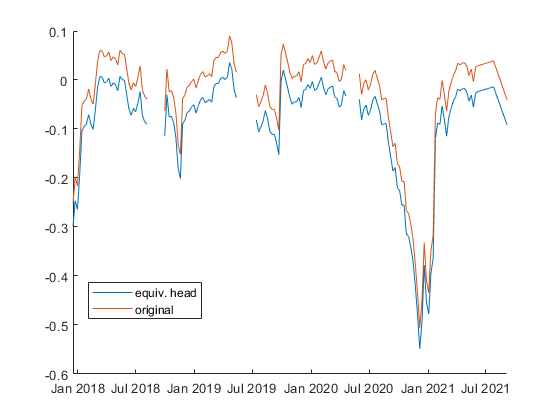

%Calculate Equivalent head given variable density over time
BLM93 = innerjoin(BflatHour,BLM93);
BLM93 = EquivHead(BLM93, 308, BSFWellDatabase, BLM93.Density_calculated__BLM93_gcm3, BLM93.HaliteSaturatedDensity);

BLM93Cand93joined = innerjoin(BLM93C,BLM93); %Join so can plot difference in head between two wells

figure
tiledlayout (5,1)

#### Density measurements

nexttile([2,1])
hold on 
plot(BflatHour.Date_Time_MDT, BflatHour.HaliteSaturatedDensity, 'color', [0 1 1],'linewidth', 1, 'DisplayName','modeled halite-saturated density')

yline(mean(BflatHour.HaliteSaturatedDensity, 'omitnan'),':','color',[0 0 1], 'DisplayName','mean halite-saturated density')

plot(BflatHour.Date_Time_MDT, BflatHour.Density_calculated__BLM93_gcm3,'color', [0.9290 0.6940 0.1250],'linewidth', 1, 'DisplayName','3.5 m deep well density from 10 cm temp.')
plot(BLM93.Date_Time_MDT, BLM93.Density_calculated_100cmdepth_gcm3,'color', [1 0 0],'linewidth', 1, 'DisplayName','3.5 m deep well density from 100 cm temp.')

scatter(BLM93Density.Date, BLM93Density.FieldDensitygcm, 20, [0.6350 0.0780 0.1840], 'filled', 'DisplayName','3.5  m well measured brine density')
scatter(BLM93CDensity.Date, BLM93CDensity.FieldDensitygcm, 20, [0 0.4470 0.7410], 'filled', 'DisplayName','0.8 m well measured brine density')
yline(mean(BflatHour.Density_calculated__BLM93_gcm3, 'omitnan'),':','color',[0.8350 0.0780 0.10], 'DisplayName','mean 3.5 m well density')

xlim(BflatHour.Date_Time_MDT([5000,end]))
ylabel('density (g cm^-^3)')
xline(BflatHour.Date_Time_MDT([26000]), 'displayname', '(b) & (c) period start')
title('comparison of measured and calculated density')
legend('location', 'bestoutside')

% figure
% tiledlayout flow

#### Equivalent head

nexttile([1,1])
hold on 

plot(BLM93C.Date_Time_MDT, -BLM93C.WaterLevelBelowSurface_m*100,':', 'color', [0 0.4470 0.7410],'linewidth', 2.5,'DisplayName','0.8 m well water depth')
plot(BLM93.Date_Time_MDT, -BLM93.WaterLevelBelowSurface_m*100,'color', [0.6350 0.0780 0.1840],'linewidth', 1.5, 'DisplayName','3.5 m well water depth')
plot(BLM93.Date_Time_MDT, -BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m*100,'color', [0.9290 0.6940 0.1250],'linewidth', 1.5,  'DisplayName','3.5 m well const. density equiv. head')
plot(BLM93.Date_Time_MDT, -BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_variabledensity*100,'color', [0.1290 0.6940 0.1250],'linewidth', 1.5,  'DisplayName','3.5 m well var. density equiv. head')

xlim(BflatHour.Date_Time_MDT([26000,end]))
% legend('location','eastoutside')
legend('location','southwest')
ylabel('water depth (cm)')
title('measured water depth and calculated equivalent head')

#### Measurement Difference

nexttile([1,1])
plot(BLM93.Date_Time_MDT, (BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m - BLM93.EquivalentHead_HaliteSaturated_BelowSurf_m_variabledensity)*100, 'DisplayName','variable density') %density of saturated sample and overall changes with this
ylabel('cm of difference')
xlim(BflatHour.Date_Time_MDT([26000,end]))
title('difference between constant and variable density head calculations')

#### Vertical gradient in head over time

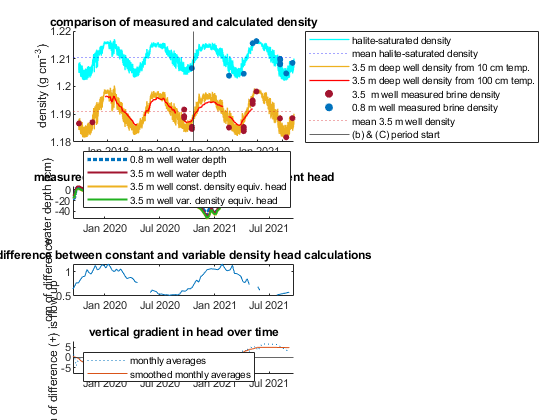

nexttile([1,1])
hold on 
plot(BLM93Cand93joined.Date_Time_MDT, -100*(BLM93Cand93joined.EquivalentHead_HaliteSaturated_BelowSurf_m_BLM93 - BLM93Cand93joined.EquivalentHead_HaliteSaturated_BelowSurf_m_BLM93C), ...
    ":", 'DisplayName','monthly averages')
plot(BLM93Cand93joined.Date_Time_MDT, -100*smoothdata((BLM93Cand93joined.EquivalentHead_HaliteSaturated_BelowSurf_m_BLM93 - BLM93Cand93joined.EquivalentHead_HaliteSaturated_BelowSurf_m_BLM93C),...
    'movmean','SmoothingFactor',0.2), 'DisplayName','smoothed monthly averages')

yline(0, 'HandleVisibility','off')
ylim([-8,8])
ylabel('cm of difference (+) is flow up')
xlim(BflatHour.Date_Time_MDT([26000,end]))
title('vertical gradient in head over time')
% legend('location','eastoutside')
legend('location','northwest')

cd ..\output\
print('EquivalentHeadCorrectionSupPlot', '-fillpage','-dpdf') %'-bestfit' -fillpage

function [Well] = EquivHead(Well, WellRowNumber, BSFWellDatabase, rhoSample,rhoHalite)
%rhoHalite = 1211.1; %(kg/m3) %Reference density - mean halite saturated density using BLM93C equation and 10 cm soil temp as input

screenElevation = BSFWellDatabase.SurfaceElevation_m(WellRowNumber) - BSFWellDatabase.ScreenedInterval_midpoint_m(WellRowNumber);
headSample = BSFWellDatabase.SurfaceElevation_m(WellRowNumber) - (Well.WaterLevelBelowSurface_m);
Well.EquivalentHead_HaliteSaturated_BelowSurf_m_variabledensity = -((((rhoSample./rhoHalite).*headSample - ((rhoSample - rhoHalite)./rhoHalite).*screenElevation)) - BSFWellDatabase.SurfaceElevation_m(WellRowNumber)); 

figure
hold on
plot(Well.Date_Time_MDT, -Well.EquivalentHead_HaliteSaturated_BelowSurf_m, 'DisplayName','equiv. head')
plot(Well.Date_Time_MDT, -Well.WaterLevelBelowSurface_m, 'DisplayName','original')
xlim(Well.Date_Time_MDT([1,end]))
legend('location', 'best')
end